% IOE 511/MATH 562, University of Michigan
% Code written by: Minghao Chen
% Run for Backtracking Line Search Test

% Script to run code
% close all figures, clear all variables from workspace and clear command
% window
% close all
clear;clc;clf
format long
addpath(genpath('Methods'));
addpath(genpath('TrustRegion'));
addpath(genpath('Problems'));
addpath(genpath('Linesearch'));
addpath((genpath('Dataset')));
addpath((genpath('Output')));
addpath((genpath('Experiment')));
 

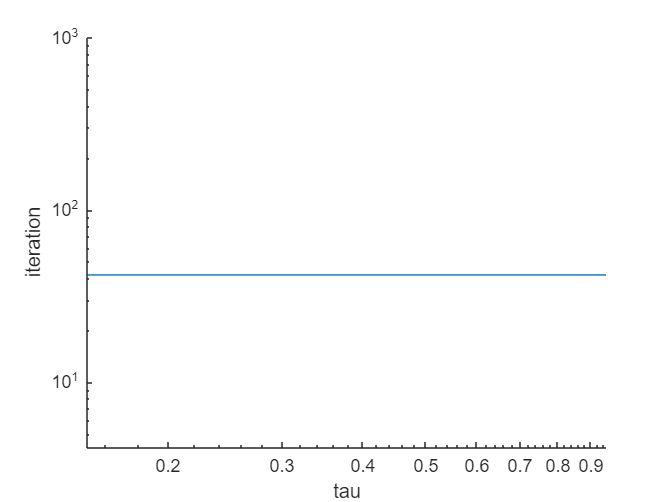

iter = 0;
time = 0;
tau = 0.05:0.1:0.95; % adjust the tested tau

for i = 0.05:0.1:0.95
tic
rng(0);
% set problem (minimal requirement: name of problem)
problem.name = "Rosenbrock_1000";
problem.x0 = [-1.2;ones(999,1)];
problem.n = length(problem.x0);
problem.memory = 5;
method.options.tau = i;
% method.options.alphaMax = i;

% set method (minimal requirement: name of method)
method.name = 'GradientDescent'; % option: GradientDescent, Newton, BFGS, L-BFGS
%method.options.constant_step_size = 1e-3;

% set options   
options.term_tol = 0.000001;
options.max_iterations = 1000;
% fstar = 1;

% h= waitbar(0,'Please wait...');
% run method and return x^* and f^*
[x,f,k,delta,norm_g] = optSolver(problem,method,options);

% output
fig_name = strcat("experiment",'.png');
result_name = strcat(problem.name,'_',method.name,'.mat');

timeElapsed = toc; 

iter = [iter;k];
time = [time;timeElapsed];

% fprintf('%15s %15s %15s %15s','Iteration','Func val','Norm Grad','CPU Seconds');
% fprintf('%15d %15.4e %15.4e %15.4f',k,f,norm_g,timeElapsed); 
% 
% result = {'k','f','norm_g','timeElapsed';k,f,norm_g,timeElapsed};
% save(strcat('Output/',result_name'), "result");

end

figure(1) %iteration plot
loglog(tau,iter(1:10));
xlabel("tau");
ylabel("iteration");
box off

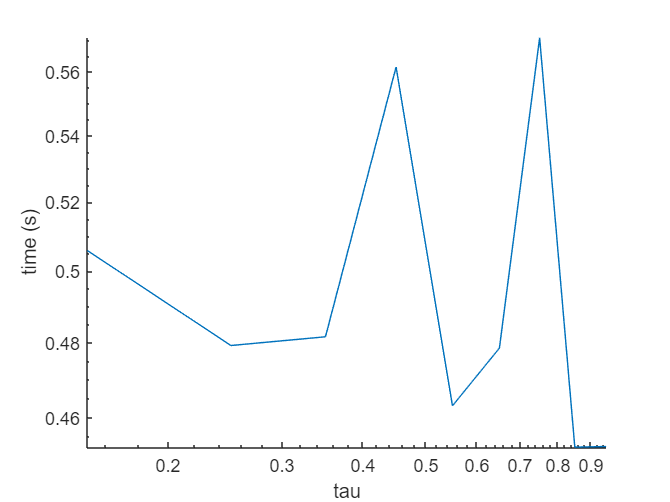

% set(gca,'Yscale','log','Xscale','log')
% set(gca,'Xscale','log')

figure(2) %time plot
loglog(tau,time(1:10));
xlabel("tau");
ylabel("time (s)");
box off